

% n = 1:30;
% 
% x= cos( n * pi / 6 +.2);
% y = zeros(size(n));
% 
% y(1) = x(1) + 0.8 * 0; % Multiplying gets amplitude at n but at zero needs time to get to amplitude
% 
% for i = 2:30
%     y(i) = x(i) + .8 * y(i-1);
% end
% 
% % Real signal has lag time while hand calculated is perfect scenario
% 
% stem(x); hold on % Makes on same plot 
% stem(y);


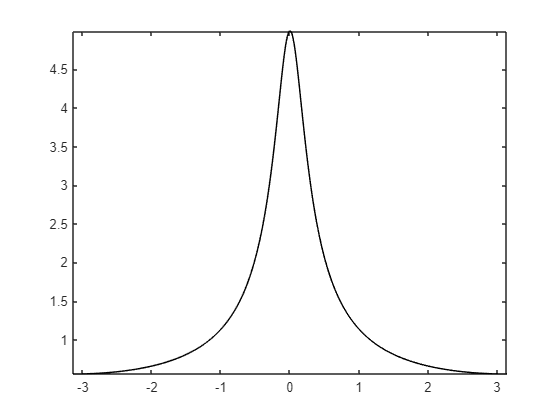

%% Using Difference equation to find Transfer, Frequency response, Amplitude(magnitude) and phase response
omega = linspace(-pi, pi, 400); 

H = @(z) z ./ (z - 0.8);

freq_response = H(exp(1j * omega));

amp_response = abs(freq_response);

phase_response = angle(freq_response); % Gets angle
% Amplitude Response Plot
plot(omega, amp_response, 'k'); axis tight

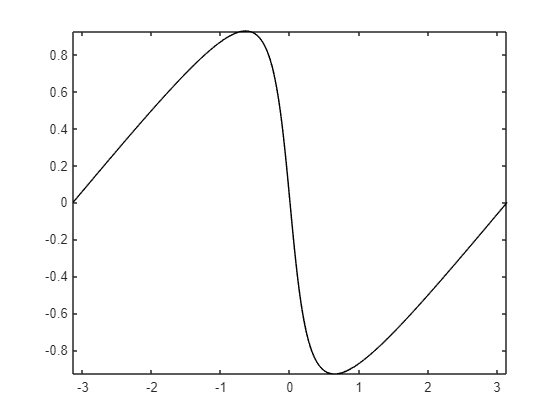

% Phase Response Plot
plot (omega, phase_response, 'k'); axis tight